# **BSP 2021-2022/1 - Assignment 02**

  **Total of 10 marks**

**Name/Neptun Code: ****     Hakan Burak KARLI/DMWBL1                             **  

**Marks attained for this homework will count towards your final grade**

**To attain (full) marks for a question, any answer that includes images or a piece of knowledge, which should be referenced/cited, needs to highlight the source (book, article or web address). You are encouraged to help each other, but identical solutions will not be graded.**

## **Signal modulation**

When you are listening to the radio, you may choose between FM and AM channels at given (*carrier*) frequencies. This means that a radio wave at this carrier frequency is frequency (FM) or amplitude modulated (AM) with the music/speech signal (*information*).

The same process is used when wireless biomedical implants transmit the signal to the external receiver, such as a pacemaker. Furthermore, modulation might be the mean of signal recording, as we will see later.

The carrier signal is a simple sine wave and can be written in the form of:

                              $c(t) = C\cdot \sin(2\pi f_ct + \Phi_c)$ ,                                                        (1)

where $C$ is the amplitude, $f_c$ is the frequency and $\Phi_c$ is the phase of the sine.

Suppose the following information signal is modulating the carrier 

                             $s(t) = S\cdot \sin(2\pi f_{sig}t +\Phi_{sig})$                                                         (2)

 In practice the AM usually goes like

                              $m(t) = [1 + s(t) )] \cdot c(t)$, if $S \leq 1$                                                (3)                      

Let's see this in practice. 

First create the common time array of the plots:

% sampling frequency of the signals - this should be at least twice
% as high as the highest signal frequency to be plotted
f_s = 500;    % Hz
t = linspace(0,1,1*f_s); % s


Define the parameters:


f_c = 100;    % Hz
C  = 1;       % V
Phi_c = pi/4; % rad

f_sig = 3;   % Hz
S = 0.5;     % V
Phi_sig = 0; % Hz


Create the signals:


c = C*sin(2*pi*f_c*t + Phi_c);
s = S*sin(2*pi*f_sig*t + Phi_sig);

m = (1 + s).*c;


Plot the resulting signals:

figure

subplot(3,1,1)
plot(t,c)
title('carrier')
xlabel('time (s)')
ylabel('amplitude (V)')
subplot(3,1,2)
plot(t,s)
title('information')
xlabel('time (s)')
ylabel('amplitude (V)')
subplot(3,1,3)
plot(t,m)
title('modulated signal')
xlabel('time (s)')
ylabel('amplitude')


### Question 1

Why should be f_s at least twice as high as f_c?

(1 mark)

### Question 2

What happens if S>1? How would you modify eq. (3) to avoid this problem?

(1 mark)

### Question 3

Using trigonometric identities ([http://www.purplemath.com/modules/idents.htm](http://www.purplemath.com/modules/idents.htm)) show what frequencies will be present on the spectrum of the modulated signal, expressed by $f_c$ and  $f_{sig}$. (*Instead of the interactive box below you can also add Latex equations using Ctrl+Shift+L*)


$$\$$


(2 marks)

## Respiratory impedance

During the measurement of the respiration signal a high-frequency current is driven through the patient’s chest (*carrier signal*). As the patient is breathing in and out, the impedance of the chest cavity varies periodically (*information*), changing the amplitude of the injected current. This changing potential *(modulated signal*) is constantly measured either on the same, or on two additional electrodes.  [[link](https://www.analog.com/en/technical-articles/transthoracic-impedance-measurements-in-patient-monitoring.html)1,[link2](http://www.google.com/patents/US20130023781)] 

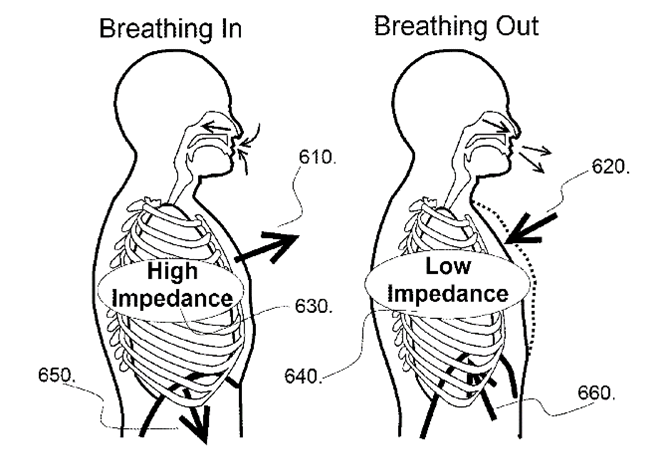

In this case the information is not a simple sine wave. However, as all signals can be written as the summation of complex sine waves (i.e. the Fourier transform), the above equations will hold meaning.

### Question 4

Download the mod_rep_sig.mat file from Moodle, which is a modulated respiratory impedance signal. Load and plot the signal in time and frequency domain, by completing the code below.

clear all;

% load the signal as variable 'm'
load 'mod_resp_sig.mat'
% sampling frequency of the downloaded signal
f_s = 10000; % Hz

% time array of the plot
t =  ;
% frequency array of the plot
f =  ;
% fourier transform of the signal
fourier_m =  ;

figure
subplot(3,1,1)
plot( )
title('Time domain')
xlabel('time (s)')
ylabel('amplitude')

subplot(3,1,2)
plot( )
title('Frequency domain')
xlabel('time (Hz)')
ylabel('amplitude')

subplot(3,1,3)
plot( )
title('Zoomed-in frequency domain')
xlabel('time (Hz)')
ylabel('amplitude')
xlim([1800,2200])
ylim([0,100])

(2 marks)

### Question 5

What is the breathing rate of the patient? Using Table 1 in  [[link](https://www.analog.com/en/technical-articles/transthoracic-impedance-measurements-in-patient-monitoring.html)1], what age group do you assume the patient to be in?

Is the impedance increasing or decreasing during breathing in? (See [[link](https://www.analog.com/en/technical-articles/transthoracic-impedance-measurements-in-patient-monitoring.html)1])

How does the posture of the patient influence the measurement? (See [[link](https://www.analog.com/en/technical-articles/transthoracic-impedance-measurements-in-patient-monitoring.html)1])

What was the frequency of the carrier signal? What is the maximum allowable drive current at this frequency? (See [[link](https://www.analog.com/en/technical-articles/transthoracic-impedance-measurements-in-patient-monitoring.html)1])

(2 marks)

### Question 6

Using your answer in Question 3 and the identity $f(x)\cdot g(x) = F(x)*G(x)$ (multiplication in the time domain = convolution in the frequency domain) explain what you can see. (Remember, what a single/double sided spectrum is, and what a convolution with a dirac delta means.) 

(2 mark)

**Do not forget to generate a pdf report from this file (Save/ Export to PDF). You should upload both the pdf and mlx files to moodle.**